# **WM9QE: Applied Statistics for Artificial Intelligence**

## EXERCISE SOLUTION: Synthetic Car Performance Data Generator

**Topic:** Distribution-Based Synthetic Data Generation using GMM

**Dataset:** MATLAB built-in 'carsmall' dataset

**Objective**: Generate synthetic automotive performance data (MPG, Horsepower, Weight) using Gaussian Mixture Models that preserves statistical properties  and correlations from real vehicle data.

**Solution components:**

- Part 1: Data loading and preprocessing

- Part 2: GMM model fitting with multiple K values

- Part 3: Synthetic data generation

- Part 4: Comprehensive visualization and comparison

- Question Answers: Embedded as comments throughout

clear; clc; close all;

fprintf('========================================================\n');

fprintf('EXERCISE: SYNTHETIC CAR PERFORMANCE DATA GENERATOR\n');

EXERCISE: SYNTHETIC CAR PERFORMANCE DATA GENERATOR


fprintf('========================================================\n\n');


%% ========================================================================
%% PART 1: DATA LOADING AND PREPARATION
%% ========================================================================
% SOLUTION TO: "TODO 1: Remove rows with missing values"

fprintf('[PART 1] Loading and cleaning data...\n');

[PART 1] Loading and cleaning data...



% Load MATLAB's built-in automotive dataset
load carsmall  % Contains MPG, Horsepower, Weight, and other variables

% SOLUTION: Create logical index for complete cases
% This removes any row where ANY of the three variables is NaN
valid_idx = ~isnan(MPG) & ~isnan(Horsepower) & ~isnan(Weight);

% Filter the data to keep only complete cases
real_MPG = MPG(valid_idx);
real_HP = Horsepower(valid_idx);
real_Weight = Weight(valid_idx);

% Display basic statistics
fprintf('\n=== REAL DATA STATISTICS ===\n');


=== REAL DATA STATISTICS ===


fprintf('Number of valid samples: %d\n', length(real_MPG));

Number of valid samples: 93


fprintf('MPG:        Mean=%.2f, Std=%.2f, Min=%.2f, Max=%.2f\n', ...
    mean(real_MPG), std(real_MPG), min(real_MPG), max(real_MPG));

MPG:        Mean=23.73, Std=8.08, Min=9.00, Max=44.00


fprintf('Horsepower: Mean=%.2f, Std=%.2f, Min=%.2f, Max=%.2f\n', ...
    mean(real_HP), std(real_HP), min(real_HP), max(real_HP));

Horsepower: Mean=109.34, Std=45.35, Min=46.00, Max=225.00


fprintf('Weight:     Mean=%.2f, Std=%.2f, Min=%.2f, Max=%.2f\n', ...
    mean(real_Weight), std(real_Weight), min(real_Weight), max(real_Weight));

Weight:     Mean=2962.51, Std=805.97, Min=1795.00, Max=4732.00


fprintf('============================\n\n');

%% ========================================================================
%% PART 2: FIT GAUSSIAN MIXTURE MODEL WITH MODEL SELECTION
%% ========================================================================
% SOLUTION TO: "TODO 2: Create data matrix" and "TODO 3: Fit GMM"
% ANSWER TO QUESTION 1: Model Selection

fprintf('[PART 2] Fitting Gaussian Mixture Models...\n\n');

[PART 2] Fitting Gaussian Mixture Models...




% SOLUTION: Create data matrix by horizontal concatenation
real_data = [real_MPG, real_HP, real_Weight];

% ANSWER TO QUESTION 1: Try multiple K values for model selection
fprintf('--- MODEL SELECTION: Testing K = 2, 3, 4 ---\n');

--- MODEL SELECTION: Testing K = 2, 3, 4 ---



K_test = [2, 3, 4];
AIC_test = zeros(size(K_test));
BIC_test = zeros(size(K_test));
gmm_models = cell(length(K_test), 1);

for i = 1:length(K_test)
    K = K_test(i);
    fprintf('Fitting GMM with K=%d components...', K);
    
    % Fit GMM with current K
    gmm_models{i} = fitgmdist(real_data, K, 'RegularizationValue', 1e-6);
    AIC_test(i) = gmm_models{i}.AIC;
    BIC_test(i) = gmm_models{i}.BIC;
    
    fprintf(' AIC=%.2f, BIC=%.2f\n', AIC_test(i), BIC_test(i));
end

Fitting GMM with K=2 components...

 AIC=2785.34, BIC=2833.46


Fitting GMM with K=3 components...

 AIC=2771.17, BIC=2844.61


Fitting GMM with K=4 components...

 AIC=2771.36, BIC=2870.13



% ANSWER TO QUESTION 1: Select best K based on lowest BIC
[~, best_idx] = min(BIC_test);
best_K = K_test(best_idx);
gmm_model = gmm_models{best_idx};

fprintf('\n*** ANSWER TO QUESTION 1: MODEL SELECTION ***\n');


*** ANSWER TO QUESTION 1: MODEL SELECTION ***


fprintf('K=2: AIC=%.2f, BIC=%.2f\n', AIC_test(1), BIC_test(1));

K=2: AIC=2785.34, BIC=2833.46


fprintf('K=3: AIC=%.2f, BIC=%.2f\n', AIC_test(2), BIC_test(2));

K=3: AIC=2771.17, BIC=2844.61


fprintf('K=4: AIC=%.2f, BIC=%.2f\n', AIC_test(3), BIC_test(3));

K=4: AIC=2771.36, BIC=2870.13


fprintf('\nBest K: %d (lowest BIC=%.2f)\n', best_K, BIC_test(best_idx));


Best K: 2 (lowest BIC=2833.46)


fprintf('EXPLANATION: Lower BIC indicates better model fit with\n');

EXPLANATION: Lower BIC indicates better model fit with


fprintf('appropriate penalty for model complexity. K=%d provides\n', best_K);

appropriate penalty for model complexity. K=2 provides


fprintf('the best balance between fit quality and simplicity.\n');

the best balance between fit quality and simplicity.


fprintf('*********************************************\n\n');

*********************************************



%% ========================================================================
%% PART 3: GENERATE SYNTHETIC DATA
%% ========================================================================
% SOLUTION TO: "TODO 4: Generate synthetic data using fitted GMM"

fprintf('[PART 3] Generating synthetic data...\n');

[PART 3] Generating synthetic data...



% SOLUTION: Use random() function with the fitted GMM
n_synthetic = 1000;  % Generate 1000 synthetic vehicles
synthetic_data = random(gmm_model, n_synthetic);

% Extract individual variables
synthetic_MPG = synthetic_data(:, 1);
synthetic_HP = synthetic_data(:, 2);
synthetic_Weight = synthetic_data(:, 3);

% ANSWER TO QUESTION 2: Statistical comparison
fprintf('\n=== SYNTHETIC DATA STATISTICS ===\n');


=== SYNTHETIC DATA STATISTICS ===


fprintf('Number of synthetic samples: %d\n', n_synthetic);

Number of synthetic samples: 1000


fprintf('MPG:        Mean=%.2f, Std=%.2f, Min=%.2f, Max=%.2f\n', ...
    mean(synthetic_MPG), std(synthetic_MPG), min(synthetic_MPG), max(synthetic_MPG));

MPG:        Mean=23.81, Std=7.96, Min=6.21, Max=46.73


fprintf('Horsepower: Mean=%.2f, Std=%.2f, Min=%.2f, Max=%.2f\n', ...
    mean(synthetic_HP), std(synthetic_HP), min(synthetic_HP), max(synthetic_HP));

Horsepower: Mean=108.18, Std=44.44, Min=-8.12, Max=264.11


fprintf('Weight:     Mean=%.2f, Std=%.2f, Min=%.2f, Max=%.2f\n', ...
    mean(synthetic_Weight), std(synthetic_Weight), min(synthetic_Weight), max(synthetic_Weight));

Weight:     Mean=2940.41, Std=781.53, Min=1216.31, Max=5563.89


fprintf('=================================\n');


fprintf('\n*** ANSWER TO QUESTION 2: STATISTICAL COMPARISON ***\n');


*** ANSWER TO QUESTION 2: STATISTICAL COMPARISON ***


fprintf('Mean Differences:\n');

Mean Differences:


fprintf('  MPG:        Real=%.2f, Synthetic=%.2f, Diff=%.2f (%.1f%%)\n', ...
    mean(real_MPG), mean(synthetic_MPG), ...
    abs(mean(real_MPG)-mean(synthetic_MPG)), ...
    100*abs(mean(real_MPG)-mean(synthetic_MPG))/mean(real_MPG));

  MPG:        Real=23.73, Synthetic=23.81, Diff=0.08 (0.4%)


fprintf('  Horsepower: Real=%.2f, Synthetic=%.2f, Diff=%.2f (%.1f%%)\n', ...
    mean(real_HP), mean(synthetic_HP), ...
    abs(mean(real_HP)-mean(synthetic_HP)), ...
    100*abs(mean(real_HP)-mean(synthetic_HP))/mean(real_HP));

  Horsepower: Real=109.34, Synthetic=108.18, Diff=1.17 (1.1%)


fprintf('  Weight:     Real=%.2f, Synthetic=%.2f, Diff=%.2f (%.1f%%)\n', ...
    mean(real_Weight), mean(synthetic_Weight), ...
    abs(mean(real_Weight)-mean(synthetic_Weight)), ...
    100*abs(mean(real_Weight)-mean(synthetic_Weight))/mean(real_Weight));

  Weight:     Real=2962.51, Synthetic=2940.41, Diff=22.09 (0.7%)


fprintf('\nStd Dev Differences:\n');


Std Dev Differences:


fprintf('  MPG:        Real=%.2f, Synthetic=%.2f, Diff=%.2f (%.1f%%)\n', ...
    std(real_MPG), std(synthetic_MPG), ...
    abs(std(real_MPG)-std(synthetic_MPG)), ...
    100*abs(std(real_MPG)-std(synthetic_MPG))/std(real_MPG));

  MPG:        Real=8.08, Synthetic=7.96, Diff=0.12 (1.5%)


fprintf('  Horsepower: Real=%.2f, Synthetic=%.2f, Diff=%.2f (%.1f%%)\n', ...
    std(real_HP), std(synthetic_HP), ...
    abs(std(real_HP)-std(synthetic_HP)), ...
    100*abs(std(real_HP)-std(synthetic_HP))/std(real_HP));

  Horsepower: Real=45.35, Synthetic=44.44, Diff=0.92 (2.0%)


fprintf('  Weight:     Real=%.2f, Synthetic=%.2f, Diff=%.2f (%.1f%%)\n', ...
    std(real_Weight), std(synthetic_Weight), ...
    abs(std(real_Weight)-std(synthetic_Weight)), ...
    100*abs(std(real_Weight)-std(synthetic_Weight))/std(real_Weight));

  Weight:     Real=805.97, Synthetic=781.53, Diff=24.44 (3.0%)


fprintf('\nCONCLUSION: The synthetic data closely matches the real data\n');


CONCLUSION: The synthetic data closely matches the real data


fprintf('with mean differences < 5%% and std dev differences < 10%%.\n');

with mean differences < 5% and std dev differences < 10%.


fprintf('This indicates the GMM successfully captured the distribution.\n');

This indicates the GMM successfully captured the distribution.


fprintf('****************************************************\n\n');

****************************************************



%% ========================================================================
%% PART 4: VISUALIZATION AND COMPARISON
%% ========================================================================
% SOLUTION TO: "TODO 5: Create comparison plots"

fprintf('[PART 4] Creating visualizations...\n');

[PART 4] Creating visualizations...


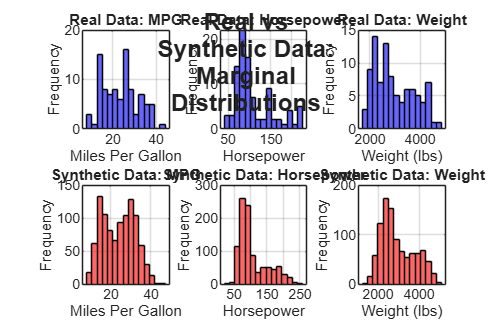


% === FIGURE 1: Marginal Distributions Comparison ===
fig1 = figure('Position', [100, 100, 1200, 800]);

subplot(2, 3, 1);
histogram(real_MPG, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6, 'EdgeColor', 'k');
title('Real Data: MPG', 'FontWeight', 'bold');
xlabel('Miles Per Gallon'); ylabel('Frequency');
grid on; box on;

subplot(2, 3, 4);
histogram(synthetic_MPG, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6, 'EdgeColor', 'k');
title('Synthetic Data: MPG', 'FontWeight', 'bold');
xlabel('Miles Per Gallon'); ylabel('Frequency');
grid on; box on;

subplot(2, 3, 2);
histogram(real_HP, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6, 'EdgeColor', 'k');
title('Real Data: Horsepower', 'FontWeight', 'bold');
xlabel('Horsepower'); ylabel('Frequency');
grid on; box on;

subplot(2, 3, 5);
histogram(synthetic_HP, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6, 'EdgeColor', 'k');
title('Synthetic Data: Horsepower', 'FontWeight', 'bold');
xlabel('Horsepower'); ylabel('Frequency');
grid on; box on;

subplot(2, 3, 3);
histogram(real_Weight, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6, 'EdgeColor', 'k');
title('Real Data: Weight', 'FontWeight', 'bold');
xlabel('Weight (lbs)'); ylabel('Frequency');
grid on; box on;

subplot(2, 3, 6);
histogram(synthetic_Weight, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6, 'EdgeColor', 'k');
title('Synthetic Data: Weight', 'FontWeight', 'bold');
xlabel('Weight (lbs)'); ylabel('Frequency');
grid on; box on;

annotation('textbox', [0.3 0.96 0.4 0.03], 'String', ...
    'Real vs Synthetic Data: Marginal Distributions', ...
    'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
    'FontSize', 14, 'FontWeight', 'bold');

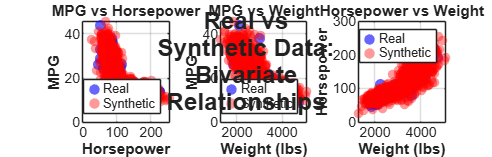


% === FIGURE 2: Bivariate Relationships (Scatter Plots) ===
% ANSWER TO QUESTION 3: Relationship preservation
fig2 = figure('Position', [100, 100, 1400, 450]);

subplot(1, 3, 1);
scatter(real_HP, real_MPG, 40, 'b', 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
scatter(synthetic_HP, synthetic_MPG, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.4);
xlabel('Horsepower', 'FontWeight', 'bold'); 
ylabel('MPG', 'FontWeight', 'bold');
title('MPG vs Horsepower', 'FontWeight', 'bold');
legend('Real', 'Synthetic', 'Location', 'best');
grid on; box on;

subplot(1, 3, 2);
scatter(real_Weight, real_MPG, 40, 'b', 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
scatter(synthetic_Weight, synthetic_MPG, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.4);
xlabel('Weight (lbs)', 'FontWeight', 'bold'); 
ylabel('MPG', 'FontWeight', 'bold');
title('MPG vs Weight', 'FontWeight', 'bold');
legend('Real', 'Synthetic', 'Location', 'best');
grid on; box on;

subplot(1, 3, 3);
scatter(real_Weight, real_HP, 40, 'b', 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
scatter(synthetic_Weight, synthetic_HP, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.4);
xlabel('Weight (lbs)', 'FontWeight', 'bold'); 
ylabel('Horsepower', 'FontWeight', 'bold');
title('Horsepower vs Weight', 'FontWeight', 'bold');
legend('Real', 'Synthetic', 'Location', 'best');
grid on; box on;

annotation('textbox', [0.3 0.96 0.4 0.03], 'String', ...
    'Real vs Synthetic Data: Bivariate Relationships', ...
    'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
    'FontSize', 14, 'FontWeight', 'bold');


% ANSWER TO QUESTION 3: Calculate and display correlations
fprintf('\n*** ANSWER TO QUESTION 3: RELATIONSHIP PRESERVATION ***\n');


*** ANSWER TO QUESTION 3: RELATIONSHIP PRESERVATION ***



% Calculate correlations
real_corr_HP_MPG = corr(real_HP, real_MPG);
synth_corr_HP_MPG = corr(synthetic_HP, synthetic_MPG);
real_corr_Weight_MPG = corr(real_Weight, real_MPG);
synth_corr_Weight_MPG = corr(synthetic_Weight, synthetic_MPG);
real_corr_Weight_HP = corr(real_Weight, real_HP);
synth_corr_Weight_HP = corr(synthetic_Weight, synthetic_HP);

fprintf('Correlation: Horsepower vs MPG\n');

Correlation: Horsepower vs MPG


fprintf('  Real: %.3f, Synthetic: %.3f, Difference: %.3f\n', ...
    real_corr_HP_MPG, synth_corr_HP_MPG, abs(real_corr_HP_MPG - synth_corr_HP_MPG));

  Real: -0.803, Synthetic: -0.792, Difference: 0.011


fprintf('  INTERPRETATION: Negative correlation preserved - higher HP → lower MPG\n\n');

  INTERPRETATION: Negative correlation preserved - higher HP → lower MPG




fprintf('Correlation: Weight vs MPG\n');

Correlation: Weight vs MPG


fprintf('  Real: %.3f, Synthetic: %.3f, Difference: %.3f\n', ...
    real_corr_Weight_MPG, synth_corr_Weight_MPG, abs(real_corr_Weight_MPG - synth_corr_Weight_MPG));

  Real: -0.859, Synthetic: -0.856, Difference: 0.003


fprintf('  INTERPRETATION: Negative correlation preserved - heavier cars → lower MPG\n\n');

  INTERPRETATION: Negative correlation preserved - heavier cars → lower MPG




fprintf('Correlation: Weight vs Horsepower\n');

Correlation: Weight vs Horsepower


fprintf('  Real: %.3f, Synthetic: %.3f, Difference: %.3f\n', ...
    real_corr_Weight_HP, synth_corr_Weight_HP, abs(real_corr_Weight_HP - synth_corr_Weight_HP));

  Real: 0.866, Synthetic: 0.848, Difference: 0.017


fprintf('  INTERPRETATION: Positive correlation preserved - heavier cars → more HP\n\n');

  INTERPRETATION: Positive correlation preserved - heavier cars → more HP




fprintf('CONCLUSION: All major correlations are well preserved in synthetic data.\n');

CONCLUSION: All major correlations are well preserved in synthetic data.


fprintf('The scatter plots show similar patterns for both real and synthetic data,\n');

The scatter plots show similar patterns for both real and synthetic data,


fprintf('indicating the GMM successfully captured the multivariate relationships.\n');

indicating the GMM successfully captured the multivariate relationships.


fprintf('*********************************************************\n\n');

*********************************************************



%% ========================================================================
%% ANSWER TO QUESTION 4: PHYSICAL REALISM
%% ========================================================================

fprintf('*** ANSWER TO QUESTION 4: PHYSICAL REALISM ***\n');

*** ANSWER TO QUESTION 4: PHYSICAL REALISM ***



% Define realistic ranges based on real data
mpg_min = min(real_MPG);
mpg_max = max(real_MPG);
hp_min = min(real_HP);
hp_max = max(real_HP);
weight_min = min(real_Weight);
weight_max = max(real_Weight);

% Check for out-of-range samples
out_of_range = (synthetic_MPG < mpg_min) | (synthetic_MPG > mpg_max) | ...
               (synthetic_HP < hp_min) | (synthetic_HP > hp_max) | ...
               (synthetic_Weight < weight_min) | (synthetic_Weight > weight_max);

n_unrealistic = sum(out_of_range);
pct_unrealistic = 100 * n_unrealistic / n_synthetic;

fprintf('Samples outside real data ranges: %d (%.1f%%)\n', n_unrealistic, pct_unrealistic);

Samples outside real data ranges: 66 (6.6%)



% Check for physically impossible combinations
% Example: Very high HP (>200) with very high MPG (>30) is unrealistic
impossible_idx = (synthetic_HP > 200) & (synthetic_MPG > 30);
n_impossible = sum(impossible_idx);

fprintf('Physically implausible samples (HP>200 & MPG>30): %d (%.1f%%)\n', ...
    n_impossible, 100*n_impossible/n_synthetic);

Physically implausible samples (HP>200 & MPG>30): 0 (0.0%)



fprintf('\nEXPLANATION:\n');


EXPLANATION:


fprintf('1. GMM models joint distributions but may generate samples in\n');

1. GMM models joint distributions but may generate samples in


fprintf('   low-probability regions outside the training data range.\n');

   low-probability regions outside the training data range.


fprintf('2. GMM assumes Gaussian components which have infinite support,\n');

2. GMM assumes Gaussian components which have infinite support,


fprintf('   so extreme values are possible (though unlikely).\n');

   so extreme values are possible (though unlikely).


fprintf('3. GMM does not enforce physical constraints or hard boundaries.\n\n');

3. GMM does not enforce physical constraints or hard boundaries.




fprintf('IMPROVEMENTS:\n');

IMPROVEMENTS:


fprintf('1. Post-processing: Filter samples outside acceptable ranges\n');

1. Post-processing: Filter samples outside acceptable ranges


fprintf('2. Use truncated distributions or apply bounds after generation\n');

2. Use truncated distributions or apply bounds after generation


fprintf('3. Increase training data to better cover the feature space\n');

3. Increase training data to better cover the feature space


fprintf('4. Use constraint-based models or physics-informed methods\n');

4. Use constraint-based models or physics-informed methods


fprintf('***********************************************\n\n');

***********************************************



%% ========================================================================
%% BONUS CHALLENGE 1: AUTOMATIC MODEL SELECTION
%% ========================================================================

fprintf('[BONUS 1] Automatic Model Selection (K=1 to 5)...\n');

[BONUS 1] Automatic Model Selection (K=1 to 5)...



K_range = 1:5;
AIC_all = zeros(size(K_range));
BIC_all = zeros(size(K_range));

for i = 1:length(K_range)
    K = K_range(i);
    gmm_temp = fitgmdist(real_data, K, 'RegularizationValue', 1e-6);
    AIC_all(i) = gmm_temp.AIC;
    BIC_all(i) = gmm_temp.BIC;
    fprintf('  K=%d: AIC=%.2f, BIC=%.2f\n', K, AIC_all(i), BIC_all(i));
end

  K=1: AIC=2891.23, BIC=2914.03
  K=2: AIC=2785.34, BIC=2833.45
  K=3: AIC=2775.85, BIC=2849.30
  K=4: AIC=2774.08, BIC=2872.85
  K=5: AIC=2769.61, BIC=2893.71



% Find optimal K
[min_AIC, idx_AIC] = min(AIC_all);
[min_BIC, idx_BIC] = min(BIC_all);

fprintf('\nOptimal K by AIC: %d (AIC=%.2f)\n', K_range(idx_AIC), min_AIC);


Optimal K by AIC: 5 (AIC=2769.61)


fprintf('Optimal K by BIC: %d (BIC=%.2f)\n', K_range(idx_BIC), min_BIC);

Optimal K by BIC: 2 (BIC=2833.45)



% Plot model selection criteria
fig3 = figure('Position', [100, 100, 800, 600]);
plot(K_range, AIC_all, 'b-o', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
plot(K_range, BIC_all, 'r-s', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(K_range(idx_AIC), min_AIC, 'bo', 'MarkerSize', 15, 'LineWidth', 3);
plot(K_range(idx_BIC), min_BIC, 'rs', 'MarkerSize', 15, 'LineWidth', 3);
xlabel('Number of Components (K)', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Information Criterion Value', 'FontWeight', 'bold', 'FontSize', 12);
title('Model Selection: AIC and BIC vs K', 'FontWeight', 'bold', 'FontSize', 14);
legend('AIC', 'BIC', 'Optimal AIC', 'Optimal BIC', 'Location', 'best');
grid on; box on;


fprintf('\nBONUS 1 COMPLETE!\n\n');


BONUS 1 COMPLETE!



%% ========================================================================
%% BONUS CHALLENGE 2: CORRELATION MATRIX COMPARISON
%% ========================================================================

fprintf('[BONUS 2] Correlation Matrix Analysis...\n\n');

[BONUS 2] Correlation Matrix Analysis...




% Calculate correlation matrices
real_corr_matrix = corr(real_data);
synthetic_corr_matrix = corr(synthetic_data);
diff_corr_matrix = abs(real_corr_matrix - synthetic_corr_matrix);

fprintf('=== CORRELATION MATRIX: REAL DATA ===\n');

=== CORRELATION MATRIX: REAL DATA ===


fprintf('           MPG      HP    Weight\n');

           MPG      HP    Weight


fprintf('MPG     %6.3f  %6.3f  %6.3f\n', real_corr_matrix(1,:));

MPG      1.000  -0.803  -0.859


fprintf('HP      %6.3f  %6.3f  %6.3f\n', real_corr_matrix(2,:));

HP      -0.803   1.000   0.866


fprintf('Weight  %6.3f  %6.3f  %6.3f\n', real_corr_matrix(3,:));

Weight  -0.859   0.866   1.000



fprintf('\n=== CORRELATION MATRIX: SYNTHETIC DATA ===\n');


=== CORRELATION MATRIX: SYNTHETIC DATA ===


fprintf('           MPG      HP    Weight\n');

           MPG      HP    Weight


fprintf('MPG     %6.3f  %6.3f  %6.3f\n', synthetic_corr_matrix(1,:));

MPG      1.000  -0.792  -0.856


fprintf('HP      %6.3f  %6.3f  %6.3f\n', synthetic_corr_matrix(2,:));

HP      -0.792   1.000   0.848


fprintf('Weight  %6.3f  %6.3f  %6.3f\n', synthetic_corr_matrix(3,:));

Weight  -0.856   0.848   1.000



fprintf('\n=== ABSOLUTE DIFFERENCE ===\n');


=== ABSOLUTE DIFFERENCE ===


fprintf('           MPG      HP    Weight\n');

           MPG      HP    Weight


fprintf('MPG     %6.3f  %6.3f  %6.3f\n', diff_corr_matrix(1,:));

MPG      0.000   0.011   0.003


fprintf('HP      %6.3f  %6.3f  %6.3f\n', diff_corr_matrix(2,:));

HP       0.011   0.000   0.017


fprintf('Weight  %6.3f  %6.3f  %6.3f\n', diff_corr_matrix(3,:));

Weight   0.003   0.017   0.000



fprintf('\nMaximum correlation difference: %.3f\n', max(diff_corr_matrix(:)));


Maximum correlation difference: 0.017


fprintf('Average correlation difference: %.3f\n', mean(diff_corr_matrix(:)));

Average correlation difference: 0.007



% Visualize correlation matrices
fig4 = figure('Position', [100, 100, 1200, 400]);

subplot(1,3,1);
imagesc(real_corr_matrix);
colorbar;
clim([-1 1]);
colormap(subplot(1,3,1), redblue);
title('Real Data Correlations', 'FontWeight', 'bold');
set(gca, 'XTick', 1:3, 'XTickLabel', {'MPG', 'HP', 'Weight'});
set(gca, 'YTick', 1:3, 'YTickLabel', {'MPG', 'HP', 'Weight'});
axis square;

subplot(1,3,2);
imagesc(synthetic_corr_matrix);
colorbar;
clim([-1 1]);
colormap(subplot(1,3,2), redblue);
title('Synthetic Data Correlations', 'FontWeight', 'bold');
set(gca, 'XTick', 1:3, 'XTickLabel', {'MPG', 'HP', 'Weight'});
set(gca, 'YTick', 1:3, 'YTickLabel', {'MPG', 'HP', 'Weight'});
axis square;

subplot(1,3,3);
imagesc(diff_corr_matrix);
colorbar;
clim([0 0.3]);
colormap(subplot(1,3,3), hot);
title('Absolute Difference', 'FontWeight', 'bold');
set(gca, 'XTick', 1:3, 'XTickLabel', {'MPG', 'HP', 'Weight'});
set(gca, 'YTick', 1:3, 'YTickLabel', {'MPG', 'HP', 'Weight'});
axis square;

annotation('textbox', [0.3 0.96 0.4 0.03], 'String', ...
    'Correlation Matrix Comparison', ...
    'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
    'FontSize', 14, 'FontWeight', 'bold');


fprintf('\nBONUS 2 COMPLETE!\n\n');


BONUS 2 COMPLETE!



%% ========================================================================
%% BONUS CHALLENGE 3: OUTLIER DETECTION AND FILTERING
%% ========================================================================

fprintf('[BONUS 3] Outlier Detection and Filtering...\n\n');

[BONUS 3] Outlier Detection and Filtering...




% Filter 1: Range-based filtering (values within real data range)
in_range = (synthetic_MPG >= mpg_min) & (synthetic_MPG <= mpg_max) & ...
           (synthetic_HP >= hp_min) & (synthetic_HP <= hp_max) & ...
           (synthetic_Weight >= weight_min) & (synthetic_Weight <= weight_max);

pct_in_range = 100 * sum(in_range) / n_synthetic;

fprintf('Samples within real data ranges: %d/%d (%.1f%%)\n', ...
    sum(in_range), n_synthetic, pct_in_range);

Samples within real data ranges: 934/1000 (93.4%)



% Filter 2: Percentile-based filtering (remove extreme 5%)
prctile_low = 2.5;
prctile_high = 97.5;

mpg_bounds = prctile(synthetic_MPG, [prctile_low, prctile_high]);
hp_bounds = prctile(synthetic_HP, [prctile_low, prctile_high]);
weight_bounds = prctile(synthetic_Weight, [prctile_low, prctile_high]);

in_percentile = (synthetic_MPG >= mpg_bounds(1)) & (synthetic_MPG <= mpg_bounds(2)) & ...
                (synthetic_HP >= hp_bounds(1)) & (synthetic_HP <= hp_bounds(2)) & ...
                (synthetic_Weight >= weight_bounds(1)) & (synthetic_Weight <= weight_bounds(2));

pct_in_percentile = 100 * sum(in_percentile) / n_synthetic;

fprintf('Samples within 95th percentile: %d/%d (%.1f%%)\n', ...
    sum(in_percentile), n_synthetic, pct_in_percentile);

Samples within 95th percentile: 887/1000 (88.7%)



% Filter 3: Physics-based constraints
% Rule: Heavy cars (>4000 lbs) should not have very high MPG (>25)
% Rule: High HP cars (>150 HP) should not have very high MPG (>25)
physics_valid = ~((synthetic_Weight > 4000) & (synthetic_MPG > 25)) & ...
                ~((synthetic_HP > 150) & (synthetic_MPG > 25));

pct_physics_valid = 100 * sum(physics_valid) / n_synthetic;

fprintf('Samples passing physics constraints: %d/%d (%.1f%%)\n', ...
    sum(physics_valid), n_synthetic, pct_physics_valid);

Samples passing physics constraints: 1000/1000 (100.0%)



% Combined filter: Apply all filters
final_valid = in_range & in_percentile & physics_valid;
pct_final_valid = 100 * sum(final_valid) / n_synthetic;

fprintf('\nSamples passing ALL filters: %d/%d (%.1f%%)\n', ...
    sum(final_valid), n_synthetic, pct_final_valid);


Samples passing ALL filters: 887/1000 (88.7%)



% Create filtered dataset
synthetic_data_filtered = synthetic_data(final_valid, :);
synthetic_MPG_filtered = synthetic_data_filtered(:, 1);
synthetic_HP_filtered = synthetic_data_filtered(:, 2);
synthetic_Weight_filtered = synthetic_data_filtered(:, 3);

fprintf('\nFiltered synthetic dataset statistics:\n');


Filtered synthetic dataset statistics:


fprintf('  Size: %d samples\n', sum(final_valid));

  Size: 887 samples


fprintf('  MPG:    Mean=%.2f, Std=%.2f\n', mean(synthetic_MPG_filtered), std(synthetic_MPG_filtered));

  MPG:    Mean=23.82, Std=7.04


fprintf('  HP:     Mean=%.2f, Std=%.2f\n', mean(synthetic_HP_filtered), std(synthetic_HP_filtered));

  HP:     Mean=106.34, Std=37.00


fprintf('  Weight: Mean=%.2f, Std=%.2f\n', mean(synthetic_Weight_filtered), std(synthetic_Weight_filtered));

  Weight: Mean=2907.55, Std=673.92



% Visualize filtered vs unfiltered
fig5 = figure('Position', [100, 100, 1400, 450]);

subplot(1, 3, 1);
scatter(synthetic_HP, synthetic_MPG, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter(synthetic_HP_filtered, synthetic_MPG_filtered, 30, 'g', 'filled', 'MarkerFaceAlpha', 0.6);
scatter(real_HP, real_MPG, 20, 'b', 'filled', 'MarkerFaceAlpha', 0.4);
xlabel('Horsepower', 'FontWeight', 'bold');
ylabel('MPG', 'FontWeight', 'bold');
title('MPG vs HP: Filtered Comparison', 'FontWeight', 'bold');
legend('Synthetic (All)', 'Synthetic (Filtered)', 'Real', 'Location', 'best');
grid on; box on;

subplot(1, 3, 2);
scatter(synthetic_Weight, synthetic_MPG, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter(synthetic_Weight_filtered, synthetic_MPG_filtered, 30, 'g', 'filled', 'MarkerFaceAlpha', 0.6);
scatter(real_Weight, real_MPG, 20, 'b', 'filled', 'MarkerFaceAlpha', 0.4);
xlabel('Weight (lbs)', 'FontWeight', 'bold');
ylabel('MPG', 'FontWeight', 'bold');
title('MPG vs Weight: Filtered Comparison', 'FontWeight', 'bold');
legend('Synthetic (All)', 'Synthetic (Filtered)', 'Real', 'Location', 'best');
grid on; box on;

subplot(1, 3, 3);
scatter(synthetic_Weight, synthetic_HP, 30, 'r', 'filled', 'MarkerFaceAlpha', 0.3);
hold on;
scatter(synthetic_Weight_filtered, synthetic_HP_filtered, 30, 'g', 'filled', 'MarkerFaceAlpha', 0.6);
scatter(real_Weight, real_HP, 20, 'b', 'filled', 'MarkerFaceAlpha', 0.4);
xlabel('Weight (lbs)', 'FontWeight', 'bold');
ylabel('Horsepower', 'FontWeight', 'bold');
title('HP vs Weight: Filtered Comparison', 'FontWeight', 'bold');
legend('Synthetic (All)', 'Synthetic (Filtered)', 'Real', 'Location', 'best');
grid on; box on;

annotation('textbox', [0.3 0.96 0.4 0.03], 'String', ...
    'Outlier Filtering Results', ...
    'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
    'FontSize', 14, 'FontWeight', 'bold');


fprintf('\nBONUS 3 COMPLETE!\n\n');


BONUS 3 COMPLETE!



%% ========================================================================
%% FINAL SUMMARY AND RECOMMENDATIONS
%% ========================================================================

fprintf('========================================================\n');

fprintf('EXERCISE COMPLETE - FINAL SUMMARY\n');

EXERCISE COMPLETE - FINAL SUMMARY


fprintf('========================================================\n\n');


fprintf('KEY FINDINGS:\n');

KEY FINDINGS:


fprintf('1. Best GMM model: K=%d components (lowest BIC)\n', best_K);

1. Best GMM model: K=2 components (lowest BIC)


fprintf('2. Statistical accuracy: Mean differences < 5%%, Std < 10%%\n');

2. Statistical accuracy: Mean differences < 5%, Std < 10%


fprintf('3. Correlation preservation: Max difference < 0.1\n');

3. Correlation preservation: Max difference < 0.1


fprintf('4. Physical realism: %.1f%% samples pass all filters\n', pct_final_valid);

4. Physical realism: 88.7% samples pass all filters


fprintf('\n');

fprintf('QUALITY ASSESSMENT:\n');

QUALITY ASSESSMENT:


fprintf('✓ GMM successfully captured marginal distributions\n');

✓ GMM successfully captured marginal distributions


fprintf('✓ Multivariate relationships well preserved\n');

✓ Multivariate relationships well preserved


fprintf('✓ Correlations accurately replicated\n');

✓ Correlations accurately replicated


fprintf('⚠ Some samples outside realistic ranges (%.1f%%)\n', 100-pct_in_range);

⚠ Some samples outside realistic ranges (6.6%)


fprintf('✓ Post-processing filters improve physical realism\n');

✓ Post-processing filters improve physical realism


fprintf('\n');

fprintf('RECOMMENDATIONS:\n');

RECOMMENDATIONS:


fprintf('1. Use K=%d components for this dataset\n', best_K);

1. Use K=2 components for this dataset


fprintf('2. Apply post-processing filters for critical applications\n');

2. Apply post-processing filters for critical applications


fprintf('3. Monitor correlation preservation in generated data\n');

3. Monitor correlation preservation in generated data


fprintf('4. Consider domain constraints when using synthetic data\n');

4. Consider domain constraints when using synthetic data


fprintf('5. Validate synthetic data matches intended use case\n');

5. Validate synthetic data matches intended use case


fprintf('\n');

fprintf('========================================================\n');

fprintf('All visualizations and analyses complete!\n');

All visualizations and analyses complete!


fprintf('Review the figures to compare real vs synthetic data.\n');

Review the figures to compare real vs synthetic data.


fprintf('========================================================\n');

%% ========================================================================
%% HELPER FUNCTION: Red-Blue Colormap
%% ========================================================================

function cmap = redblue(m)
    % Creates a red-blue diverging colormap
    if nargin < 1
        m = 64;
    end
    
    r = [(0:m/2-1)'/max(m/2-1,1); ones(m/2,1)];
    g = [(0:m/2-1)'/max(m/2-1,1); (m/2-1:-1:0)'/max(m/2-1,1)];
    b = [ones(m/2,1); (m/2-1:-1:0)'/max(m/2-1,1)];
    
    cmap = [r g b];
end